# 7/12入力の微分方程式を解く

syms a k x x0
dotx=-k*sign(x)*abs(x)^a

$$dotx = -k\,{\left|x\right|}^{a}\,\mathrm{sign}\left(x\right)$$

Tx0=abs(x0)^(1-a)/(k*(1-a))

$$Tx0 = -\frac{{\left|x_{0}\right|}^{1-a}}{k\,\left(a-1\right)}$$

clear a k x
x0=1

x0 = 1

tspan=0:0.01:4;
k=1

k = 1

a=0.1

a = 0.1000

Tx0=abs(x0)^(1-a)/(k*(1-a))

Tx0 = 1.1111

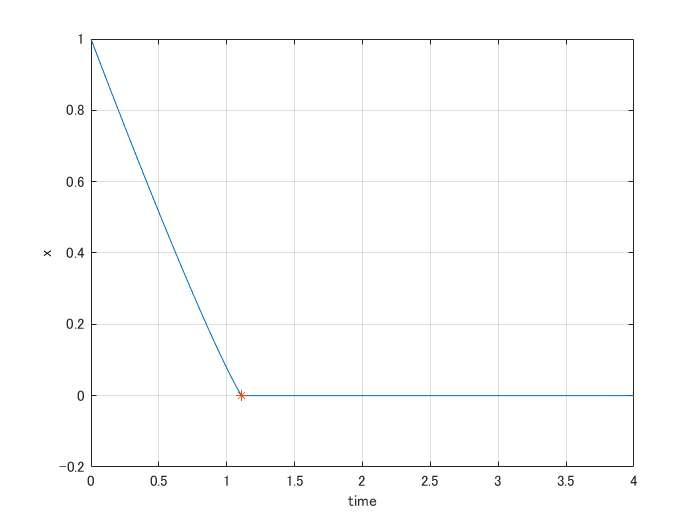

[T,X] = ode45(@(t,x) -k*sign(x)*abs(x)^a,tspan,x0);
plot(T,X)
hold on
plot(Tx0,0,'*')
grid on
hold off
xlabel('time')
ylabel('x')

%%
syms ap positive
syms an negative
syms x(t) k a x0

odep=diff(x)== -k*sign(x)*abs(x)^ap;
odeo=diff(x)== -k*sign(x)*abs(x)^1;
oden=diff(x)== -k*sign(x)*abs(x)^an;
odesgn=diff(x)==sign(x);
odeabs=diff(x)==abs(x);
odeabsa=diff(x)==abs(x)^a;

cond=x(0)==x0

$$cond = x\left(0\right)=x_{0}$$


Sp= dsolve(odep,cond)

$$Sp = \left(\begin{array}{c} \frac{1}{{\left(\frac{x_{0}-k\,t\,{x_{0}}^{\mathrm{ap}}+\mathrm{ap}\,k\,t\,{x_{0}}^{\mathrm{ap}}}{{x_{0}}^{\mathrm{ap}}}\right)}^{\frac{1}{\mathrm{ap}-1}}}\\ {\left(-\frac{1}{{\left(-1\right)}^{\mathrm{ap}}\,\left(k\,t-\frac{{x_{0}}^{1-\mathrm{ap}}}{{\left(-1\right)}^{\mathrm{ap}}\,\left(\mathrm{ap}-1\right)}\right)\,\left(\mathrm{ap}-1\right)}\right)}^{\frac{1}{\mathrm{ap}-1}} \end{array}\right)$$

So= dsolve(odeo,cond)

$$So = {\mathrm{e}}^{\log\left(x_{0}\right)-k\,t}$$

Sn= dsolve(oden,cond)

$$Sn = \left(\begin{array}{c} -\frac{1}{{\left(\left(k\,t+\frac{{\left(-x_{0}\right)}^{1-\mathrm{an}}}{\mathrm{an}-1}\right)\,\left(\mathrm{an}-1\right)\right)}^{\frac{1}{\mathrm{an}-1}}}\\ \frac{1}{{\left(\frac{x_{0}-k\,t\,{x_{0}}^{\mathrm{an}}+\mathrm{an}\,k\,t\,{x_{0}}^{\mathrm{an}}}{{x_{0}}^{\mathrm{an}}}\right)}^{\frac{1}{\mathrm{an}-1}}} \end{array}\right)$$

Ssign=dsolve(odesgn,cond)

$$Ssign = t+x_{0}$$

Sabs=dsolve(odeabs,cond)

$$Sabs = {\mathrm{e}}^{t+\log\left(x_{0}\right)}$$

Sabsa=dsolve(odeabsa,cond)

$$Sabsa = \frac{1}{{\left(\frac{x_{0}+t\,{x_{0}}^{a}-a\,t\,{x_{0}}^{a}}{{x_{0}}^{a}}\right)}^{\frac{1}{a-1}}}$$

limit(So,t,Inf)
Snt=solve(Sn(2)==0,t,'ReturnConditions',true)

Snt = フィールドをもつ struct :
             t: [1×1 sym]
    parameters: [1×0 sym]
    conditions: [1×1 sym]


Sot=solve(So==0,t,'ReturnConditions',true)

Sot = フィールドをもつ struct :
             t: [0×1 sym]
    parameters: [1×0 sym]
    conditions: [0×1 sym]


## 7/15

%入力の近似の微分方程式
syms a k x 
dotx=-k*tanh(a*x)-k*x

$$dotx = -k\,x-k\,\tanh\left(a\,x\right)$$


clear a k x
x0=1

x0 = 1

tspan=0:0.01:4;
k=1

k = 1

a=2

a = 2

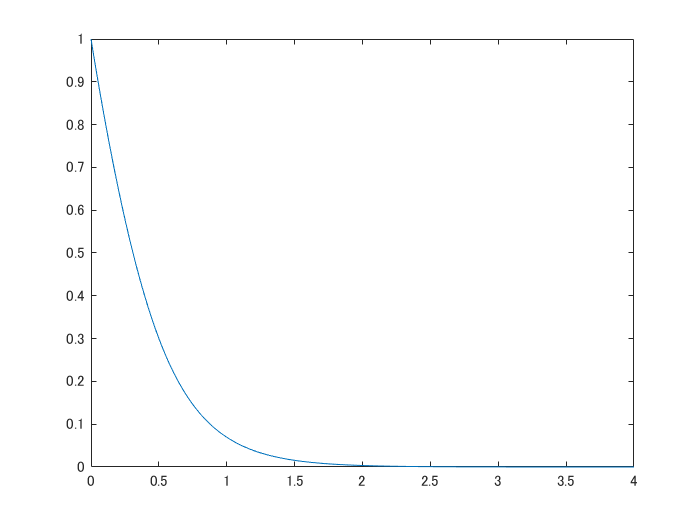

[T,X] = ode45(@(t,x) -k*tanh(a*x)-k*x,tspan,x0);
plot(T,X)

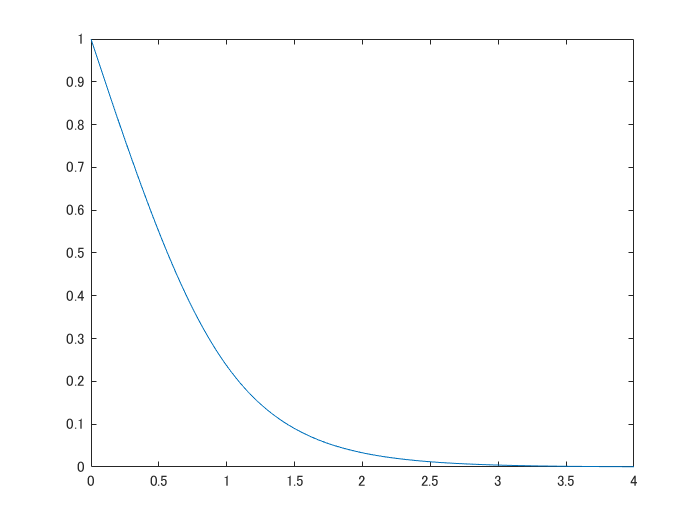

[T,X] = ode45(@(t,x) -k*tanh(a*x),tspan,x0);
plot(T,X)

syms x(t) k a t x0
cond=x(0)==x0;
odeth=diff(x)== -k*tanh(a*x);%-k*x;
Sth= dsolve(odeth,cond)

$$Sth = \begin{array}{l} \left(\begin{array}{c} \frac{\log\left(-\frac{{\mathrm{e}}^{-a\,k\,t}\,\left({\mathrm{e}}^{-a\,x_{0}}-{\mathrm{e}}^{a\,x_{0}}+\sigma_{1}\right)}{2}\right)}{a}\\ \frac{\log\left(\frac{{\mathrm{e}}^{-a\,k\,t}\,\left({\mathrm{e}}^{a\,x_{0}}-{\mathrm{e}}^{-a\,x_{0}}+\sigma_{1}\right)}{2}\right)}{a} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{4\,{\mathrm{e}}^{2\,a\,k\,t}+{\left({\mathrm{e}}^{a\,x_{0}}-{\mathrm{e}}^{-a\,x_{0}}\right)}^{2}} \end{array}$$


limit(Sth,t,Inf)
Stht=solve(Sth(1)==0,t,'ReturnConditions',true)

%入力の近似の微分
syms fz(x) z(t) dtanh ddtanh dddtanh k
dtanh=diff(k*fz(x),t)

$$dtanh = 0$$

ddtanh=diff(dtanh,t)

$$ddtanh = 0$$

dddtanh=diff(ddtanh,t)

$$dddtanh = 0$$


diff(tanh(z),t)

$$ans(t) = -\left({\tanh\left(z\left(t\right)\right)}^{2}-1\right)\,\frac{\partial }{\partial t}z\left(t\right)$$